# Observador

clear; close all; clc; 
addpath("data/");
addpath("data/tests");
load("DatosStepsVariables.mat");
load("DatosPID.mat");
theta_0 = 89;  % inicial
[sys, ~, ~, ~] = FoundTF(theta_0); 
load("data/TF.mat"); 

% Variables de estado 
A = sys.A; 
B = sys.B; 
C = sys.C; 
D = sys.D; 

% Matrices de ponderacion 
qx1 = 100; 
qx2 = 1000000; 
r = 0.001; 

Q = [qx1 0  ;0 qx2];
R = r; 

% Diseño de lqr 
[L, S, P] = lqr(A', C', Q, R); 
L = L'

L = 1.0e+04 *

    0.0401
    3.0303



Ahat = A-L*C;
Bhat = [B L];
Chat = eye(2);
Dhat = [0];

SysHat = ss(Ahat,Bhat,Chat,Dhat);
SysHat.StateName = {'thetaHat','omegaHat'};
SysHat.OutputName = {'thetaHat','omegaHat'};
SysHat.InputName = {'PWM','theta'};
Observer = c2d(SysHat,2.5e-3,'tustin'); % Implementacion en arduino

damp(SysHat)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.06e+02     1.00e+00       1.06e+02         9.41e-03    
 -2.98e+02     1.00e+00       2.98e+02         3.36e-03    


damp(Observer)

                                                                        
   Pole       Magnitude     Damping       Frequency      Time Constant  
                                        (rad/seconds)      (seconds)    
                                                                        
  7.66e-01     7.66e-01     1.00e+00       1.07e+02         9.36e-03    
  4.57e-01     4.57e-01     1.00e+00       3.13e+02         3.20e-03    


tzero(Observer)

ans =    -1.0000
   -1.0000


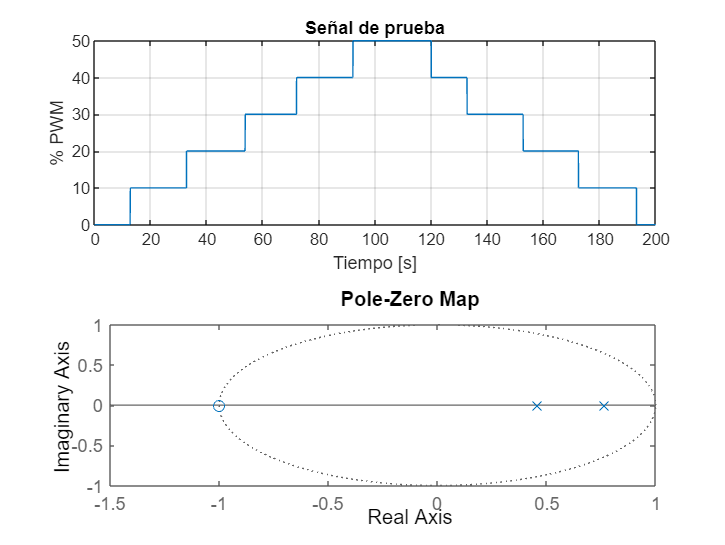


pzmap(Observer); 

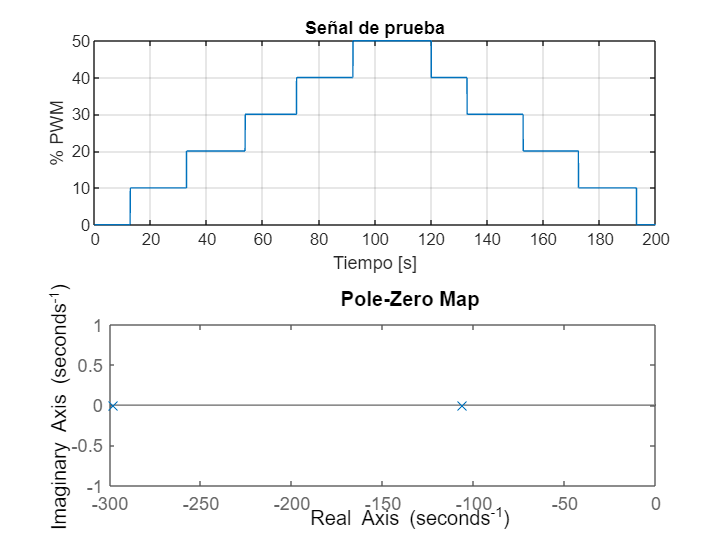

pzmap(SysHat);

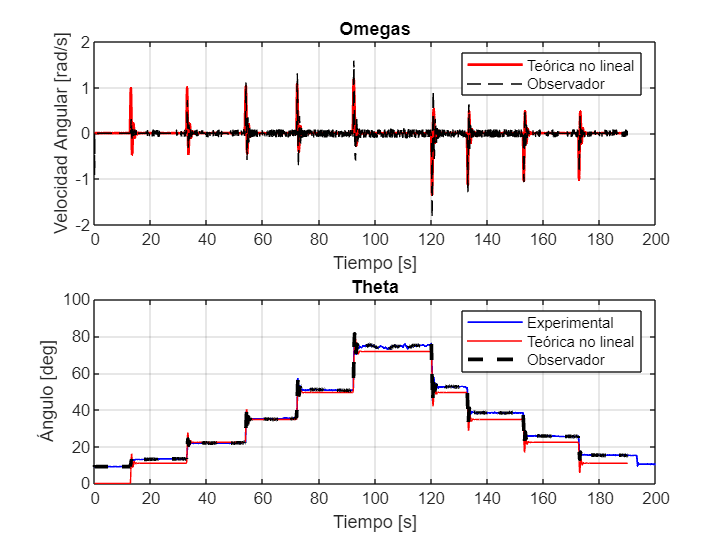


save('data/observer.mat',"L", "SysHat");
save('../implementacion/data/observer.mat', "L", "Observer"); 

addpath("sims/");
data = sim("sims/observer", 190); % Simulacion 

t = data.tout; 
% Velocities
omega = data.omega.Data ; 
omega_hat = data.omega_hat.Data;
omega_SS = data.omegaSS.Data;

% Angles 
theta = data.theta.Data ; 
theta_hat = data.theta_hat.Data ; 
theta_exp = data.theta_exp.Data; 
theta_SS = data.thetaSS.Data;

subplot(2, 1, 1); 
plot(t, omega,'r', "LineWidth",1.5)
hold on
plot(t, omega_hat, "k--", "LineWidth", 0.5); 
title("Omegas")
legend("Teórica no lineal", "Observador"); 
xlabel('Tiempo [s]')
ylabel('Velocidad Angular [rad/s]')
grid on; 

subplot(2, 1, 2); 
plot(DatosStepsVariables(:,1), DatosStepsVariables(:,3), 'b',"LineWidth", 1); 
hold on; 
plot(t, theta, 'r')
plot(t, theta_hat, "k--", "LineWidth", 2); 
hold off; 
xlim([0,200])
title("Theta")
xlabel('Tiempo [s]')
ylabel('Ángulo [deg]')
legend("Experimental", "Teórica no lineal", "Observador" ); 
grid on; 



% subplot(4,1,3)
% plot(t, omega_hat, t, omega_SS, "r--", "LineWidth", 0.5); 
% subplot(4,1,4)
% plot(t,theta_hat,t,theta_SS, "r--", "LineWidth", 0.5)

## Gráfica

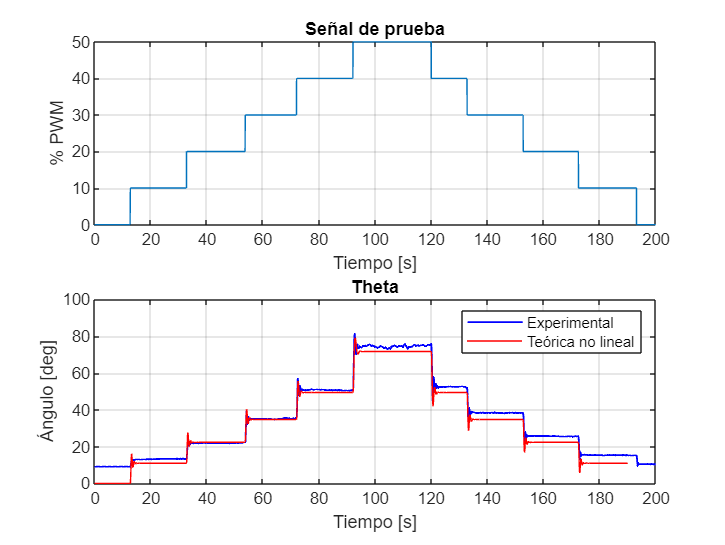

figure()
subplot(2,1,1)
plot(DatosStepsVariables(:,1), 100*DatosStepsVariables(:,2))
xlim([0 200]);
xlabel('Tiempo [s]')
ylabel('% PWM')
title('Señal de prueba')
grid on;
subplot(2,1,2)
plot(DatosStepsVariables(:,1), DatosStepsVariables(:,3), 'b',"LineWidth", 1); 
hold on; 
plot(t, theta, 'r')
hold off; 
xlim([0,200])
title("Theta")
xlabel('Tiempo [s]')
ylabel('Ángulo [deg]')
legend("Experimental", "Teórica no lineal" ); 
grid on; 

## Implementación Arduino

L

L = 1.0e+04 *

    0.0401
    3.0303


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



integrador =  1/s;
intDiscrete = c2d(integrador,2.5e-3,'tustin')

intDiscrete =
 
  0.00125 z + 0.00125
  -------------------
         z - 1
 
Sample time: 0.0025 seconds
Discrete-time transfer function.




sys

sys =
 
  A = 
            theta    omega
   theta        0        1
   omega  -0.8957   -3.334
 
  B = 
              u1
   theta       0
   omega  0.9745
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          u1
   theta   0
 
Continuous-time state-space model.



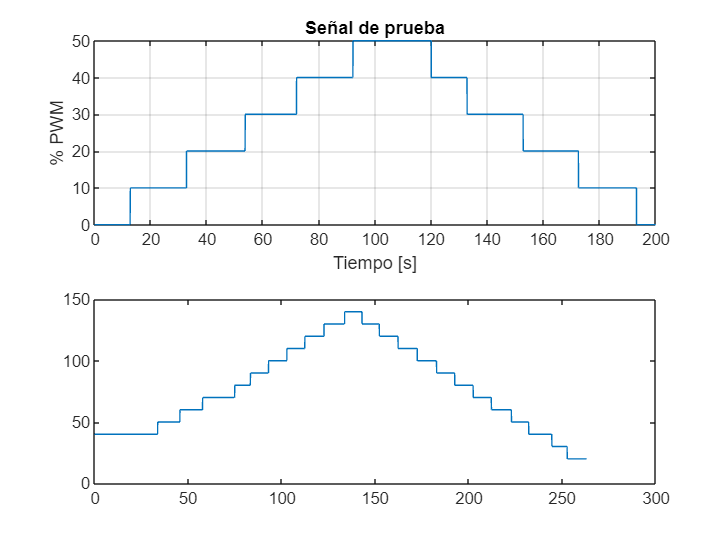

plot(DatosPID(:,1),DatosPID(:,4))